### **FinalProject_TestCode.mlx** gives example use of  Servo pHAT, pi-Cam, GPS and 12bit AtoD sensor functions for Planetary Rover.

This script creates the code using a set of pre-made functions to control the 3 Rover RC servomotors (steering, drive and payload motor) attached to the three pwm ports on a standard SparkFun Servo-pHAT board (you can easily figure out how to attached the pan-tilt servos if you use them), to talk to the Rover's qwiic based SparkFun GPS sensor and to read analog sensors from the two qwiic based SparkFun 12bit ADC boards. The drivers for the Servo pHat are in a file called **I2C_Servo_pHAT.m** which must be in same folder as this code. Please use the **snapshotCustom.m** function with your Pi-Cam, it must also be in the same folder as this code. Please add the **ads1015.m** function to this folder to support your two 12ADC boards. And finally use the **UBX_CLASS_ID.m, UBX.M **and **NEO_M8U.m**  files for your GPS, they all must also be in the same working folder as this code.

* There is a lot of complex device driver code in these supplimentary MATLAB files, please don't open and mess with them, they can't be easily fixed if you break something.*

**Wiring assumptions **(note: if you change your Rover's wiring you must change code to match !):

It is assumed that the three motors are connected to the pHAT through an Actobotics Servo Power isolation board (as shown below), and that the power isolation board is set up to recieve an RC style **pwm** velocity commands from the  Pi Servo pHAT and 7.2 VDC power from the rovers battery through its speed control unit. 

1) Please plug steering motor into pHAT-channel 1 and drive motor amplifier into pHAT-channel 3 as shown. Plug Your payload, pan and tilt servos into any other odd numbered spots.  

2) Please connect your SparkFun GPS-16329 GPS to Qwiic serial bus as shown, be extremly careful with interface cable bewteen SMA and UFL antena cable, you can only plug it into your GPS once or twice. Once plugged in properly, please never remove it. Your GPS is really expensive and this set of hardware is the ONLY ONE, your team gets. No spares.

3) Please add the two SparkFun Qwiic ADC boards to the Qwiic bus as shown and then carefully attached all of your Sharp IR and Maxbotix Sonars to them. You will need to permenantly modify address and pot jumpers on these boards so that internal pot and addresses don't conlict. See Dave B for modification details.   

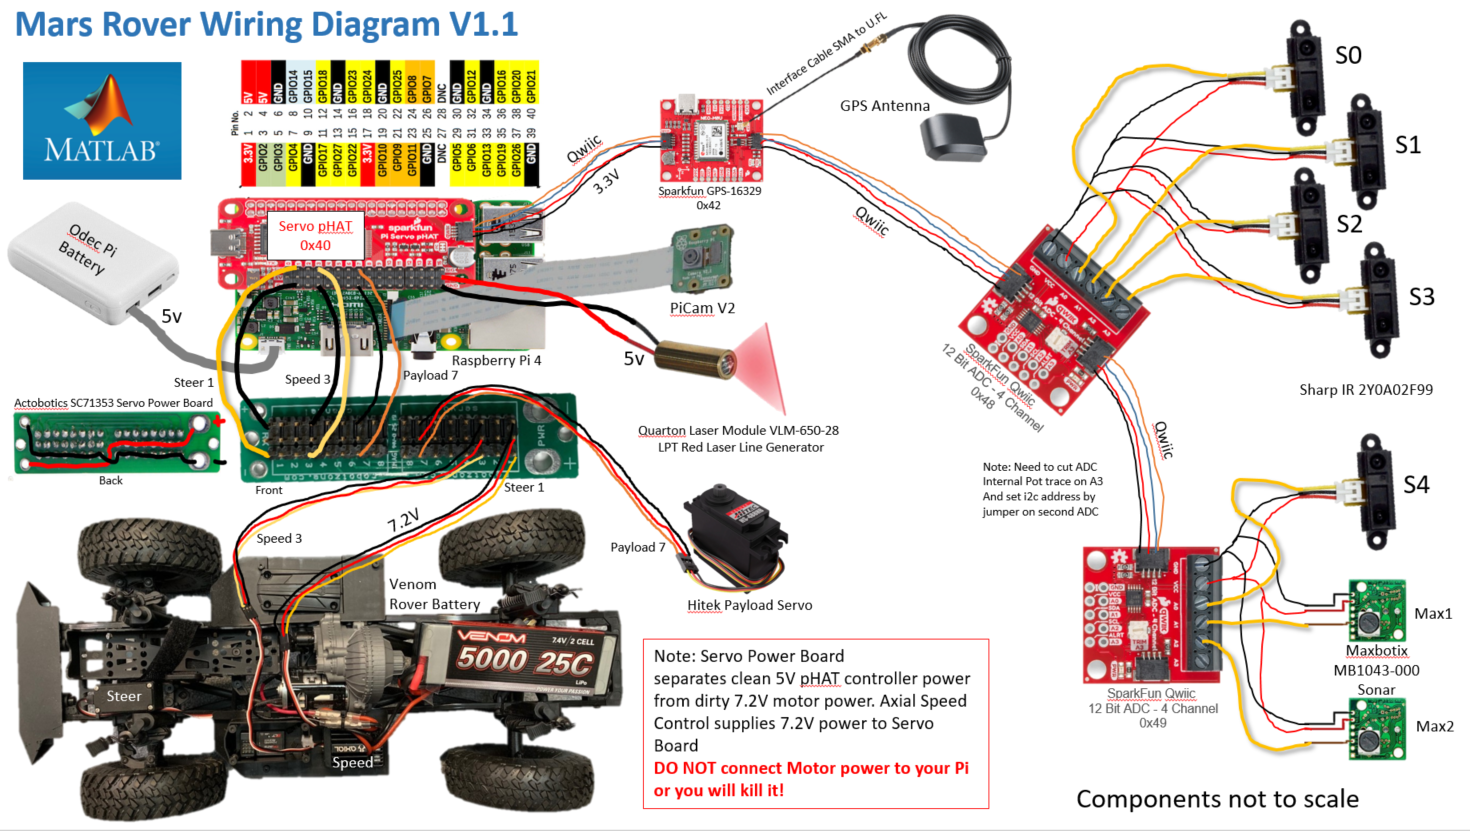

This test code is a scafolding for your Rover control code. This Script will first set up each of the hardware subsystems and create the OCU displays to observe them (code that runs once) and then will move into a continuous loop so that you can experimentally collect data from them for your Rover code (code that runs in control loop). It will aslo let you collect your Rover's current GPS position as well as observe the raw input analog signal voltage from your Rover's Sharp IR Range and Maxbotic Sonar sensors. You will still need to add calibration code to each of those to turn those voltages into useful range measurements. Please note, because of the wierdness of runing interperted code over a WiFi link to the Pi, this loop will run very slowly at about 2 seconds per cycle. Thats normal. Matlab engineers and Dave are working on a path to speed this up.

**Note! Never hook up your Raspberry Pi HOT, Never ever let 7.2V battery voltage touch any Pi GPIO pins!!!!  Please don't burn out your Pi.**

*At end of each programming session, please don't forget to shutdown your Pi cleanly by using the follwing at the command line:*

## `h = robotPi`

## `h.execute('sudo shutdown -h now')`

If you don't shut down cleanly before a poweroff, you risk corrupting the Linux build on your Pi and trashing it for future use.

D. Barrett 4-4-21 and* Rev A*

clc                     % clear command window
clear                   % clear MATLAB workspace
% profile on            % profile used to time each segment of code

**Set up robot control system** ( code that runs once )

% create Raspberry PI  and RC servo ref-objects
  disp('note: It takes a 10 seconds or so to download code to Raspberry PI '); 

note: It takes a 10 seconds or so to download code to Raspberry PI 


  [robotPi, blinkLED]= SETUP_PI() 

robotPi =   raspi with properties:

         DeviceAddress: '192.168.10.141'              
                  Port: 18734                         
             BoardName: 'Raspberry Pi Model B+'       
         AvailableLEDs: {'led0'}                      
  AvailableDigitalPins: [4,5,6,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27]
  AvailableSPIChannels: {'CE0','CE1'}                 
     AvailableI2CBuses: {'i2c-1'}                     
      AvailableWebcams: {'bcm2835-isp (platform:bcm2835-isp)','mmal service 16.1 (platform:bcm2835-v4l2)'}
           I2CBusSpeed: 100000                        

  Supported peripherals


blinkLED = 'led0'

% Turn on board LED on and off to signal program has started 
  Blink(robotPi,blinkLED,10);
  disp('Warning! Robot Rover Active! '); 

Warning! Robot Rover Active! 


Check everything is plugged in on i2c Qwiic bus (should see devices at  servo 0x40, GPS 0x42, ADC 0x48 0x49, Pi 0x70 

  scanI2CBus(robotPi)

ans = 1×5 cell array
    {'0x40'}    {'0x42'}    {'0x48'}    {'0x49'}    {'0x70'}


First, set up your Rover's Servos

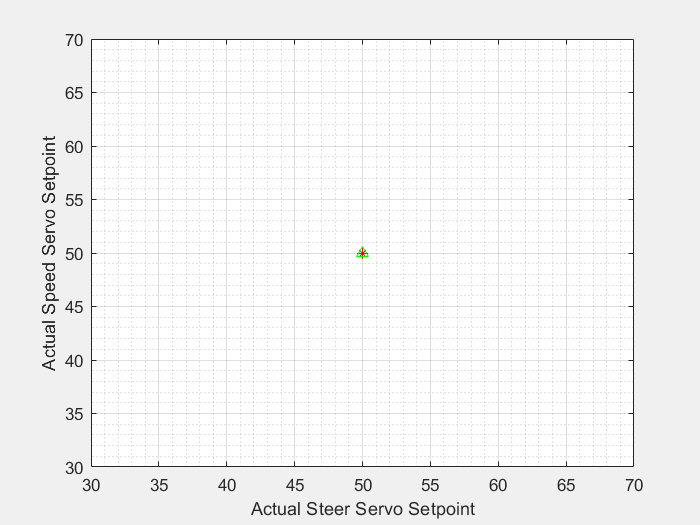

 % Configure Servo pHAT driver board (address 0x40), set servos to null position.
  roverServos = I2C_Servo_pHAT(robotPi);
  pSteer = 1;                                   % set Steer servo to pin 1
  pSpeed = 3;                                   % set Speed servo to pin 3
  comSteer = 50;                                % set intial steer command to 0 angle
  comSpeed = 50;                                % set intial speed command to 0 speed
  roverServos.setServoPWM(pSteer,comSteer);     % Set sterring servo  center position
  roverServos.setServoPWM(pSpeed,comSpeed);     % Set Rover speed  zero
  
 % Define joystick ID (if only using 1 joystick, this will likely be '1')
   ID = 1;
   
 % Create joystick variable
   roverJoy=vrjoystick(ID);
  
 % Visualize the test servo commands in robot coordinate system.
 % create a new free-standing figure to display the servo data, rover
 % at center
    localServoPlot=figure('Name','RoverServoSettings (trigger to STOP)','NumberTitle','off','Visible','on');
    PlotServoSettings(localServoPlot,comSteer,comSpeed)    

Next set up you Pi-Cam

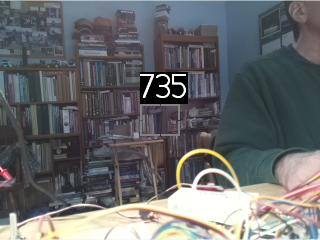

% To create a connection to the V2 Pi Camera
robotCam = cameraboard(robotPi,'Resolution','320x240');

% Fix auto exposure problem , set eposure to work in lab lighting
% set whitebalance to manual too. Auto exposure and white balance drive
% computer vison algorythms crazy by constantly changing
SetUpPiCamera(robotCam);  

% Acquire a Frame
img = snapshotCustom(robotCam);

% Display the frame in the imaqtool window
% imaqtool launches an interactive GUI to allow you to explore, configure, 
% and acquire data from your installed and supported image acquisition devices.
% imtool(img);                 % can comment this out when you confirm all is working

% explore image with tool
% gCamTest= input('experiment with image tool, type G, then hit ENTER ','s');   % can comment this out when you confirm all is working
% clc;

% livescript does some funky stuff when you try to update in line images quickly, so
% create a free floating figure for images to deal with livescript update problem
piCamWindow = figure('name','Robot Pi Camera','NumberTitle','off','Visible','on');
figure(piCamWindow)                              % go to camWindow for imshow           
imshow(img,'Border','tight')

% create two SparkFun Qwiic Analog Input adc device that are present on i2c
% bus 1 at address 0x48 and at adress 0x49

adcDevice1 = ads1015(robotPi,'i2c-1','0x48');
adcDevice2 = ads1015(robotPi,'i2c-1','0x49');

rawRangeData1 = SENSE_ADC(adcDevice1)

rawRangeData1 =     1.3170    1.2853    1.2853    1.2852


rawRangeData2 = SENSE_ADC(adcDevice2)

rawRangeData2 =     2.0561    0.6745    0.6426    0.6425


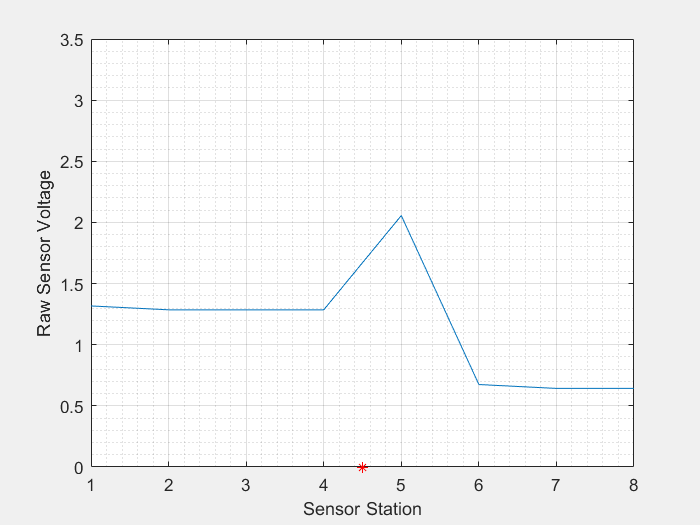

rawRangeData= [rawRangeData1,rawRangeData2];  % concatinate ADC raw vectors together

% Visualize the test sensor scan data in robot coordinate system.
% create a new free-standing figure to display the local sensor data, rover
% at center
    localSensorPlot=figure('Name','LocalSensorMap','NumberTitle','off','Visible','on');
    PlotSensorData(localSensorPlot, rawRangeData);

Create GPS object and collect first Rover GPS location

see [https://learn.sparkfun.com/tutorials/sparkfun-gps-dead-reckoning-neo-m8u-hookup-guide](https://learn.sparkfun.com/tutorials/sparkfun-gps-dead-reckoning-neo-m8u-hookup-guide) for hookup and technical details

Please see [https://learn.sparkfun.com/tutorials/three-quick-tips-about-using-ufl](https://learn.sparkfun.com/tutorials/three-quick-tips-about-using-ufl) for how to connect your ufl antenna and be 

extrodinarily careful when making the actual connection. Break this connector and GPS is toast and your team doesn't have a spare.

**Note: You will need to connect your GPS over USB to yoru laptop and run U-Center to configure your GPS before using.** See Dave for details.

1.Download the Ublox GPS application:

[https://www.u-blox.com/en/product/u-center](https://www.u-blox.com/en/product/u-center)      

2. Need to upload configuration file  “basic_cfg.txt” to GPS, see canvas for upload directions.

Note:  The time to first fix will about **~26 seconds**, but after it has a lock, that battery will allow for about a **1.5 second** time to first fix. 

This is known as a **hot start** and lasts for four hours after the board is powered down. The battery provides over a years worth of 

power to the backup system and charges slowly when the board is powered. To charge it to full, leave your module plugged in for 48 hours.

**Note: WE STILL HAVE COMPLEX TIMING BUGS IN GPS CODE, CARRY ON AND WILL GET YOU FIX WHEN ITS DONE**

% neo = NEO_M8U(robotPi);            % Create a GPS Class Instance

% neo.getBasic()
% returns a struct with fields: longitude, lattitude, roll, pitch, and heading.

% pause(2);                          % wait for GPS to get up to speed       
% basic_data = neo.getBasic()
 
 % convert lat and long for two positions to meters in X and Y ?
 % d = acos( sin φ1 ⋅ sin φ2 + cos φ1 ⋅ cos φ2 ⋅ cos Δλ ) ⋅ R
 % 	θ = atan2( sin Δλ ⋅ cos φ2 , cos φ1 ⋅ sin φ2 − sin φ1 ⋅ cos φ2 ⋅ cos Δλ )
 % where:	φ is latitude, λ is longitude, R is earth:s radius (mean radius = 6,371km);
 % note that angles need to be in radians to pass to trig functions!
 % can use above to convert position to meters from starting point 
 % then plot same on map of Oval.

Create a Mission Definition File (MDF) of Rover waypoints in a Matlab Table:

% create index fro MDF table
WayPoint = (1:1:10);                                        
WayPoint = WayPoint';

% create inital target waypoints
xLongitude = [ -71.227875 ; -71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875];
yLatitude = [ 42.276295 ; 42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ];

% build list of desired behaviors
Behavior = ['Pause___' ; 'GoToWPT_'; 'Pause___' ;'FindDock' ;'GoToWPT_' ;'Pause___' ;'FindDock' ;'GoToDock' ;'null____' ;'null____'  ];

% build Middion Definition File (MDF) table
MDF = table(WayPoint,xLongitude,yLatitude,Behavior)

MDF = 10×4 table
    WayPoint    xLongitude    yLatitude    Behavior
    ________    __________    _________    ________

        1        -71.228       42.276      Pause___
        2        -71.228       42.276      GoToWPT_
        3        -71.228       42.276      Pause___
        4        -71.228       42.276      FindDock
        5        -71.228       42.276      GoToWPT_
        6        -71.228       42.276      Pause___
        7        -71.228       42.276      FindDock
        8        -71.228       42.276      GoToDock
        9        -71.228       42.276      null____
       10        -71.228       42.276      null____


Note: use curly braces { } to extract data from a table, in this case MDF

WPn = 1;
wayPointX = MDF{WPn,2}

wayPointX = -71.2279

wayPointY = MDF{WPn,3}

wayPointY = 42.2763

roverBehavior = MDF{WPn,4} 

roverBehavior = 'Pause___'

Create global variables  and an index for tracking the iterations.

sampleTime = 0.5;                                  % Sample time [s]
t = 0:sampleTime:100;                              % Time array
r = rateControl(1/sampleTime);                     % reset control loop  rate
reset(r);                                          % reset loop time to zero

Ready to run robot, ask operator if they are set and suggest they move plots to a visable position

userInput = questdlg('Ready to run Rover?', 'Start Mission');

**Run robot control loop **( code that runs over and over )

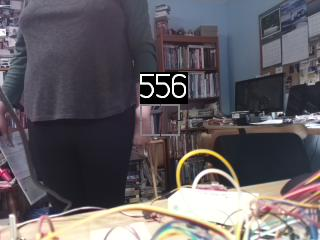

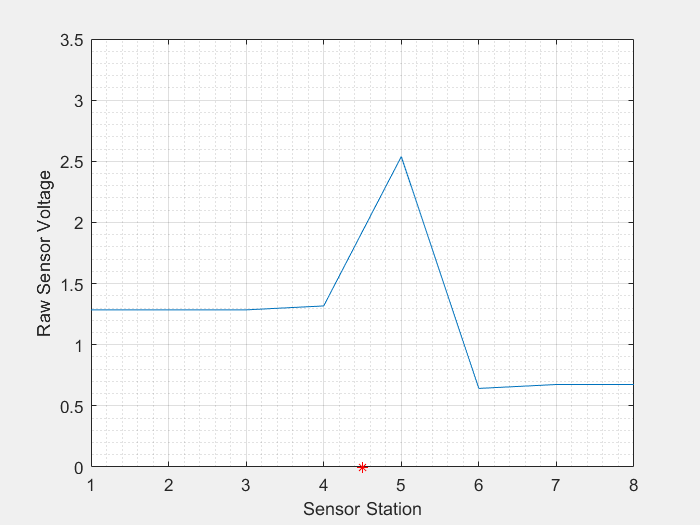

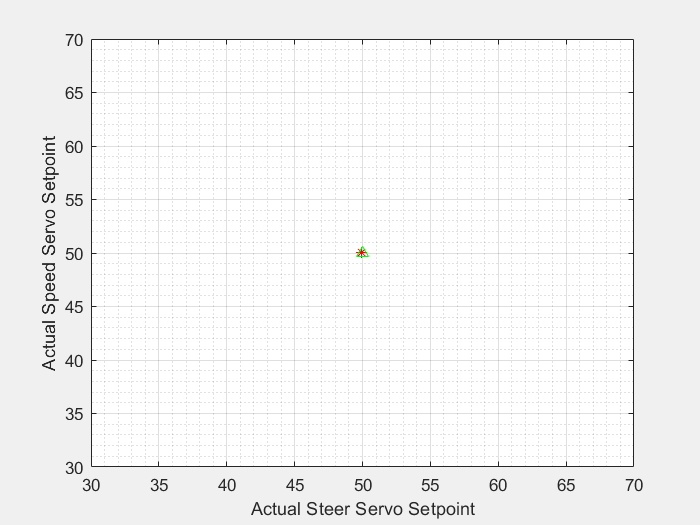

if (strcmp(userInput,'Yes'))
    comSteer = 50;                       % set steering center
    comSpeed = 50;                       % set drivespeed to zero
    controlFlag = 1;                     % create a loop control
while (controlFlag < numel(t))           % loop for number of elements in t
    
    %controlTime = r.TotalElapsedTime;    % running register of control loop time
    
    % SENSE ------------------------------
    % take joystick steer and speed commands from operator
    [comSteer, comSpeed] = SENSE_JoyStick(roverJoy);
    
    currentImage = SENSE_PiCam(robotCam);      % collect pi-cam data
    figure(piCamWindow)                        % go to piCamWindow for imshow           
    imshow(currentImage,'Border','tight')      % show pic-cam data
    
    rawAnalogRangeData = SENSE_Range(adcDevice1, adcDevice2);  % collect range data
    PlotSensorData(localSensorPlot, rawAnalogRangeData);
    
    % add a GPS read here ********************************
    
    %THINK------------------------------------------------------------
    % add code here that checks rovers curretn state with goal in MDF
    % and updates target waypoint appropriately
    WPn = 1;                                  % replace this with updating waypoint code
    wayPointX = MDF{WPn,2};
    wayPointY = MDF{WPn,3};
    roverBehavior = MDF{WPn,4}; 
    % compute what robot should do next
    [steerSetPoint, driveSetPoint] = THINK(WPn, wayPointX,wayPointY, roverBehavior);
    
    % ACT-------------------------------------------------------------
    % command both servo motors to desired velocity via joystick
    PlotServoSettings(localServoPlot,comSteer, comSpeed); 
    ActTestServoPHAT(roverServos,comSteer, comSpeed); 
    % replace above joystick code when you get your THINK code done
    % by swapping comSteer for steerSetPoint and 
    % comSpeed for driveSetPoint
    
    % stop loop by pressing joystick button 1
    b = button(roverJoy, 1);
    if (b == true)
        break;
    end
    
    waitfor(r);                          % wait for loop cycle to complete  
    controlFlag = controlFlag+1;         % increment loop
    
end 
end  % if (strcmp(userInput,'Yes'))

### Mission data processing

For many robot applications, you will need to post-process the data collected after

the mission. 

  % Plot and store mission data vs. time, maybe yoru gps rover track?
  % write experimental data to a file for later use
  % save steerServoData.dat steerServoData -ascii  
  % save driveServoData.dat driveServoData -ascii  

### Clean shut down

finally, with most embeded robot controllers, its good practice to put 

all actualtors into a safe position and then release all control objects and shut down all

communication paths. This keeps systems form jamming when you want to run again.

% Stop program and clean up the connection to Pi
% when no longer needed 
  roverServos.setServoPWM(1,50);       % Center steering Wheels
  roverServos.setServoPWM(3,50);       % Turn Drive Motor off
  close all;                           % clear data figure plots
  clc                                  % clear commad window
  clear robotPi                        % clear Pi object
  beep              % play system sound to let user know program is ended
  

Check quasi real-time loop performance (Dave and Matlab working on ways to speed this up)

  disp(r);

  rateControl with properties:

         DesiredRate: 2
       DesiredPeriod: 0.5000
       OverrunAction: 'slip'
    TotalElapsedTime: 164.1170
          LastPeriod: 0.7030



  stats = statistics(r)                % check real-time loop execution time stats

stats = struct with fields:
              Periods: [1×200 double]
           NumPeriods: 200
        AveragePeriod: 0.8175
    StandardDeviation: 0.4489
          NumOverruns: 200


  disp('Rover Test program has ended');

Rover Test program has ended


  disp('Dont forget to shut down Pi cleanly before you power it off');

Dont forget to shut down Pi cleanly before you power it off


*At end of each programming session, please don't forget to shutdown your Pi cleanly by using the follwing at the command line:*

## `h = robotPi`

## `h.execute('sudo shutdown -h now')`

  % leave next line commented out
  %  profile viewer                    % view code runtimes graphically

**Robot Functions **(store this codes local functions here)

In practice for modularity, readability and longitevity, your main robot code should be as brief as possible and the bulk of the work should be done by functions

For this Rover test LiveScript, many of the critical functions are embedded in class definitions in external files.

function [robotPi, blinkLED]= SETUP_PI()
% SETUP_Pi creates and configures a Raspberry  Pi to be a simple robot 
% controller. It requires no inputs and returns an Pi and Servo Pi objects
% D. Barrett 2021 Rev A

% Create a global raspberry PI object so that it can be used in functions
% Create a *raspi* object.
   robotPi = raspi('192.168.10.141');   % note: use your Pi's IP adress here
 
% There is a user LED on Raspberry Pi hardware that you can turn on and
% off. Execute the following command at the MATLAB prompt to turn the LED
% off and then turn it on again.
%
   blinkLED = robotPi.AvailableLEDs{1};    
end

function [] = Blink(robotPi,led, n)
  % Blink toggles Raspberry Pi LED on and off to indicate program running
  % input n is number of blinks
  % no output is returned
  % dbarrett 1/14/20
    for bIndex = 1:n
      writeLED(robotPi, led, 1);
      pause(0.1);     
      writeLED(robotPi, led, 0);
      pause(0.1);
    end
end

function [] = PlotServoSettings(localServoPlot,comSteer, comSpeed)
    % Plots Rover's steerig angle and speed on a stand alone figure
    figure(localServoPlot)
    plot(comSteer,comSpeed, 'r*');
    axis([30 70 30 70]);
    grid on;
    grid minor;
    xlabel('Actual Steer Servo Setpoint')
    ylabel ('Actual Speed Servo Setpoint')
    hold on;
    plot(50,50, 'g^');             % plot robot position 
    hold off;  
end

function [] = PlotSensorData(localSensorPlot, rawRangeData)
    % Plots Rover Sensor Data on a standalone figure
    figure(localSensorPlot)
    plot(rawRangeData)
    axis([1 8 0 3.5]);
    grid on;
    grid minor; 
    xlabel('Sensor Station')
    ylabel ('Raw Sensor Voltage')
    hold on;
    plot(4.5,0, 'r*');             % plot robot position 
    hold off;  
end



**Sense Functions** (store all Sense related local functions here)

function [comSteer, comSpeed] = SENSE_JoyStick(roverJoy)
% this function polls USB joystick and returns x position 
% for Rover steering angle and y position for Rover velocity
    stickX = axis(roverJoy, 1);     % X-axis is joystick axis 1 (-1 to 1)
    stickY = axis(roverJoy, 2);     % Y-axis is joystick axis 2 (-1 to 1)
    comSteer = 50 + (10 * stickX);  % scale X for servo with pulse centered at 50
    comSpeed = 50 + (-10 * stickY);  % scale Y for servo with pulse centered at 50
end

function []= SetUpPiCamera(robotCam)
    % creates and configures an Pi V2 Camera to be a simple robot 
    % vision system. It requires a standard Pi V2 cmaera attached to 
    % your Raspberry piand takes the picam object name as sole input
    % You need to set your cameras unique parameters to optimize picture
    % D. Barrett 2021 Rev A
    % Available resolutions: '160x120', '320x240', '640x480', '800x600', '1024x768', '1280x720', '1920x1080'
    % Available exposure modes: 'auto', 'night', 'nightpreview', 'backlight', 'spotlight', 'sports', 'snow', 
    % 'beach', 'verylong', 'fixedfps', 'antishake', 'fireworks'
    % Available AWB modes: 'off', 'auto', 'sun', 'cloud', 'shade', 'tungsten', 'fluorescent', 
    % 'incandescent', 'flash', 'horizon'
    % Available metering modes: 'average', 'spot', 'backlit', 'matrix'
    % Available image effects: 'none', 'negative', 'solarise', 'sketch', 'denoise', 
    % 'emboss', 'oilpaint', 'hatch', 'gpen', 'pastel', 'watercolour', 'film', 'blur', 'saturation', 'colourswap', 'washedout', 'posterise', 'colourpoint', 'colourbalance', 'cartoon'

    % Fix  exposure set it to respond quickly, set auto whitebalance to off
    robotCam.ExposureMode = 'sports';
    robotCam.AWBMode = 'fluorescent';
end

function [piRobotImage] = SENSE_PiCam(robotCam)
    % This function aquires a single image from the PiCamera
    % and displays it in a stand alone figure
    % D. Barrett 2021 Rev A
   piRobotImage = snapshotCustom(robotCam);     % take one image
         
end

function rawRangeDataN = SENSE_ADC(adcDeviceN)
     % read ADC1 Pin 0-4 voltage
    rawRangeDataN = [adcDeviceN.readVoltage(0), adcDeviceN.readVoltage(1), ...
                adcDeviceN.readVoltage(2), adcDeviceN.readVoltage(3)]; 
end

function [rawAnalogRangeData] = SENSE_Range(adcDevice1, adcDevice2)
     % read all adc registers and return one raw volatge vector
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawAnalogRangeData= [rawRangeData1,rawRangeData2];  % concatinate ADC raw vectors together
end

**Think Functions** (store all Think related local functions here)

function [ steerSetPoint, driveSetPoint] = THINK(WPn, wayPointx,wayPointY, roverBehavior)
   % add thinking code here
   % Behavior = ['Pause___' ; 'GoToWPT_'; 'Pause___' ;'FindDock' ;'GoToWPT_' ;'Pause___' ;'FindDock' ;'GoToDock' ;'null____' ;'null____'  ];
   WPn = WPn +0;                                              % next 5 lines are placeholders to remove complier warnings
   wayPointx = wayPointx +0 ;                                 % please replace with actual code
   wayPointY = wayPointY +0;
   notused = WPn + wayPointx + wayPointY; 
   notused = notused+0;
  
   switch roverBehavior
       case 'Pause___'
           % stop and look around?
           [ steerSetPoint, driveSetPoint] = THINK_Pause();
       case 'GoToWPT_'
           % do pure pursuit to next waypoint
           [ steerSetPoint, driveSetPoint] = THINK_GoToWPT();
       case 'FindDock'
           % look for dock?
           [ steerSetPoint, driveSetPoint] = THINK_FindDock();
       case 'GoToDock'
           % drive to dock?
           [ steerSetPoint, driveSetPoint] = THINK_GoToDock();    
       otherwise 
           % do pause behavior
           [ steerSetPoint, driveSetPoint] = THINK_Pause();
   end
   [ steerSetPointOA, driveSetPointOA] = THINK_ObAvoid();
   [ steerSetPoint, driveSetPoint] = THINK_Arbiter(steerSetPointOA, driveSetPointOA, steerSetPoint, driveSetPoint) ;
end

function [ steerSetPoint, driveSetPoint] = THINK_ObAvoid()
   % add obstacle avoid behavior here 
   steerSetPoint = 50;
   driveSetPoint = 50;
end

function [ steerSetPoint, driveSetPoint] = THINK_Pause()
   % add pause behavior here  
   steerSetPoint = 50;
   driveSetPoint = 50;
end

function [ steerSetPoint, driveSetPoint] = THINK_GoToWPT()
   % add go to waypoint behavior here 
   steerSetPoint = 50;
   driveSetPoint = 50;
end

function [ steerSetPoint, driveSetPoint] = THINK_FindDock()
   % add find dock behavior here 
   steerSetPoint = 50;
   driveSetPoint = 50;
end

function [ steerSetPoint, driveSetPoint] = THINK_GoToDock()
   % add go to dock behavior here  
   steerSetPoint = 50;
   driveSetPoint = 50;
end

function [steerSetPoint, driveSetPoint] = THINK_Arbiter(steerSetPoint1, driveSetPoint1, steerSetPoint2, driveSetPoint2)
   % add arbiter here  
   steerSetPoint = (steerSetPoint1 + steerSetPoint2)/2;
   driveSetPoint = (driveSetPoint1 + driveSetPoint2)/2;
end

**Act Functions** (store all Act related local functions here)

function ActTestServoPHAT(roverServos,steerSetPoint, driveSetPoint) 
% is an example of a function to control the two Rover RC servomotors
% Need to run SETUP_PI function first to create a Raspberry-Pi and 
% position servo objects. 
% Input SetPoint is desired position on a pulse duty cycle scale of 0-100
% Output is motion of RC steering servo and the spee dof the Rover wheels
% dbarrett 1-13-20  RevD
     
     roverServos.setServoPWM(1,steerSetPoint);    % commands steering servo
     roverServos.setServoPWM(3,driveSetPoint);    % commands drive speed controller
    
end